bring system to equilibrium

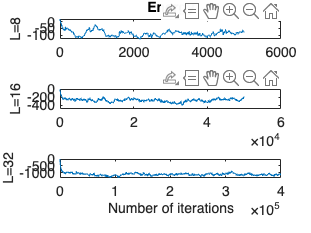

Ti=2.5;
Tf=0.1;
thermalize=[0 5000 55000 455000];%[0 16 268 1292]
sizz=[8 16 32];

rng('shuffle');


H=zeros(1,thermalize(3));


for L=1:3
    siz=sizz(L);
    matrix=rand(siz);
    
    for i=1:siz
        for j=1:siz
            if matrix(i,j)<0.5
                matrix(i,j)=-1;
            else
                matrix(i,j)=1;
            end
        end
    end
    
    periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
    
    for n=thermalize(L)+1:thermalize(L+1)
        i=randi([2,siz+1]);
        j=randi([2,siz+1]);
        old=matrix(i-1,j-1);
        new=old*(-1);
        
        Enew=-new*periodm(i,j+1)-new*periodm(i,j-1)-new*periodm(i+1,j)-new*periodm(i-1,j);
        Eold=-old*periodm(i,j+1)-old*periodm(i,j-1)-old*periodm(i+1,j)-old*periodm(i-1,j);
        
        if Enew<Eold
            matrix(i-1,j-1)=new;
            
        else
            z=rand;
            if z<exp((Eold-Enew)/Ti)
                matrix(i-1,j-1)=new;
                
            end
        end
       
        Hnew=0;
        Snew=0;
        periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
        for i=2:siz+1
            for j=2:siz+1
                Hnew=Hnew-periodm(i,j)*periodm(i,j+1)-periodm(i,j)*periodm(i+1,j); 
                Snew=Snew+periodm(i,j);
            end
        end
        H(n)=Hnew;
        S(n)=Snew;
    end   
end
figure

subplot(3,1,1)
plot(1:thermalize(2)-thermalize(1),H(1:thermalize(2)))
title('Energy')
ylabel('L=8')
subplot(3,1,2)
plot(1:thermalize(3)-thermalize(2),H(thermalize(2)+1:thermalize(3)))
ylabel('L=16')
subplot(3,1,3)
plot(1:thermalize(4)-thermalize(3),H(thermalize(3)+1:thermalize(4)))
ylabel('L=32')
xlabel('Number of iterations')
fontsize(14,'points')

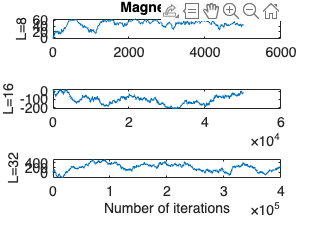



figure

subplot(3,1,1)
plot(1:thermalize(2)-thermalize(1),S(1:thermalize(2)))
title('Magnetization')
ylabel('L=8')
subplot(3,1,2)
plot(1:thermalize(3)-thermalize(2),S(thermalize(2)+1:thermalize(3)))
ylabel('L=16')
subplot(3,1,3)
plot(1:thermalize(4)-thermalize(3),S(thermalize(3)+1:thermalize(4)))
ylabel('L=32')
xlabel('Number of iterations')
fontsize(14,'points')

6 columns = H, S, C, X, binder ratio, T

Ti=5.1;
Tf=0.1;
thermalize=[1500 10000 100000];
nmax=[100000 400000 1200000];
sizz=[8 16 32];
tau=10; %passos de T igual a 1/tau 
Trange=(Ti-Tf)*tau;
J=1;

rng('shuffle');

data=zeros(Trange,6,3);%6 columns = H, S, C, X, binder ratio, T

for L=1:3
    siz=sizz(L);
    matrix=rand(siz);
    
    for i=1:siz
        for j=1:siz
            if matrix(i,j)<0.5
                matrix(i,j)=-1;
            else
                matrix(i,j)=1;
            end
        end
    end
        
    for t=1:Trange+tau
        T=Ti+1-t/tau;

        for th=1:thermalize(L)
            periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
            k=randi([2,siz+1]);
            l=randi([2,siz+1]);
            old=matrix(k-1,l-1);
            new=old*(-1);
            
            
            Enew=J*(-new*periodm(k,l+1)-new*periodm(k,l-1)-new*periodm(k+1,l)-new*periodm(k-1,l));
            Eold=J*(-old*periodm(k,l+1)-old*periodm(k,l-1)-old*periodm(k+1,l)-old*periodm(k-1,l));
            
            if Enew<Eold
                matrix(k-1,l-1)=new;
                
            else
                z=rand;
                if z<exp((Eold-Enew)/T)
                    matrix(k-1,l-1)=new;
                    
                end
            end
        end
        periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
        
        H=zeros(nmax(L),1);
        S=zeros(nmax(L),1);
        for n=1:nmax(L)
           
            k=randi([2,siz+1]);
            l=randi([2,siz+1]);
            old=matrix(k-1,l-1);
            new=old*(-1);
            
            Enew=J*(-new*periodm(k,l+1)-new*periodm(k,l-1)-new*periodm(k+1,l)-new*periodm(k-1,l));
            Eold=J*(-old*periodm(k,l+1)-old*periodm(k,l-1)-old*periodm(k+1,l)-old*periodm(k-1,l));
            
            if Enew<Eold
                matrix(k-1,l-1)=new;
                
            else
                z=rand;
                if z<exp((Eold-Enew)/T)
                    matrix(k-1,l-1)=new;
                    
                end
            end
            periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
            
            Hnew=0;
            Snew=0;
            for i=2:siz+1
                for j=2:siz+1
                    Hnew=Hnew-J*periodm(i,j)*periodm(i,j+1)-J*periodm(i,j)*periodm(i+1,j); 
                    Snew=Snew+periodm(i,j);
                end
            end
            H(n,1)=Hnew;
            S(n,1)=Snew;
        end 
        Hmean=mean(H);
        Smean=mean(S);
        Hmeansq=mean((H/siz).^2);
        Smeansq=mean((S/siz).^2);
        Smeanquad=mean(S.^4/siz^2);

        data(t,6,L)=T;
        
        data(t,1,L)=Hmean/siz^2;
        data(t,2,L)=Smean/siz^2;
        data(t,3,L)=(Hmeansq-Hmean^2/siz^2)/T^2;
        data(t,4,L)=(Smeansq-Smean^2/siz^2)/T;
        data(t,5,L)=Smeanquad/(Smeansq^2*siz^2);


    end
end


figure
subplot(3,1,1)
plot(1:thermalize(2)-thermalize(1),H(1:thermalize(2)))
subplot(3,1,2)
plot(1:thermalize(3)-thermalize(2),H(thermalize(2)+1:thermalize(3)))
subplot(3,1,3)
plot(1:thermalize(4)-thermalize(3),H(thermalize(3)+1:thermalize(4)))

Razão de Binder

Ti=2.5;
Tf=2.1;
thermalize=[1500 10000 100000];
nmax=[100000 600000 1500000];
sizz=[8 16 32];
tau=100; %passos de T igual a 1/tau 
Trange=(Ti-Tf)*tau;
J=1;

rng('shuffle');

data=zeros(round(Trange),2,3);%2 columns = ratio, T

for L=1:3
    siz=sizz(L);
    matrix=rand(siz);
    
    for i=1:siz
        for j=1:siz
            if matrix(i,j)<0.5
                matrix(i,j)=-1;
            else
                matrix(i,j)=1;
            end
        end
    end
        
    for t=1:Trange
        T=Ti-t/tau;

        for th=1:thermalize(L)
            periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
            k=randi([2,siz+1]);
            l=randi([2,siz+1]);
            old=matrix(k-1,l-1);
            new=old*(-1);
            
            
            Enew=J*(-new*periodm(k,l+1)-new*periodm(k,l-1)-new*periodm(k+1,l)-new*periodm(k-1,l));
            Eold=J*(-old*periodm(k,l+1)-old*periodm(k,l-1)-old*periodm(k+1,l)-old*periodm(k-1,l));
            
            if Enew<Eold
                matrix(k-1,l-1)=new;
                
            else
                z=rand;
                if z<exp((Eold-Enew)/T)
                    matrix(k-1,l-1)=new;
                    
                end
            end
        end
        periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
        
        H=zeros(nmax(L),1);
        S=zeros(nmax(L),1);
        for n=1:nmax(L)
           
            k=randi([2,siz+1]);
            l=randi([2,siz+1]);
            old=matrix(k-1,l-1);
            new=old*(-1);
            
            Enew=J*(-new*periodm(k,l+1)-new*periodm(k,l-1)-new*periodm(k+1,l)-new*periodm(k-1,l));
            Eold=J*(-old*periodm(k,l+1)-old*periodm(k,l-1)-old*periodm(k+1,l)-old*periodm(k-1,l));
            
            if Enew<Eold
                matrix(k-1,l-1)=new;
                
            else
                z=rand;
                if z<exp((Eold-Enew)/T)
                    matrix(k-1,l-1)=new;
                    
                end
            end
            periodm=[matrix(siz,siz) matrix(siz,:) matrix(siz,1); matrix(:,siz) matrix matrix(:,1); matrix(1,siz) matrix(1,:) matrix(1,1)];
            
            Hnew=0;
            Snew=0;
            for i=2:siz+1
                for j=2:siz+1
                    Hnew=Hnew-J*periodm(i,j)*periodm(i,j+1)-J*periodm(i,j)*periodm(i+1,j); 
                    Snew=Snew+periodm(i,j);
                end
            end
            H(n,1)=Hnew;
            S(n,1)=Snew;
        end 
        data(t,1,L)=mean(S.^4)/mean(S.^2)^2;
        
        data(t,2,L)=T;
    end
end

save('SMCbinder.mat','data')

Plot de razao de Binder

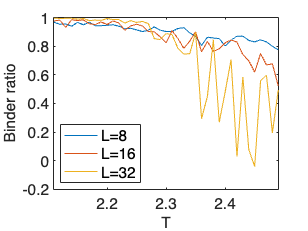

figure
plot(data(:,2,1),1/2*(3-data(:,1,1)))
hold on
plot(data(:,2,2),1/2*(3-data(:,1,2)))
hold on
plot(data(:,2,3),1/2*(3-data(:,1,3)))
hold off

legend('L=8','L=16','L=32','location', 'southwest')
xlim([2.11 2.49])
xlabel('T')
ylabel('Binder ratio')
fontsize(14,'points')

Buscando $\nu$

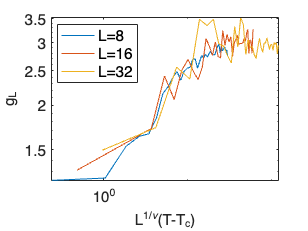

nu=1;
Tc=2.27;

indbig0=find((data(:,6,1)-Tc)>0);

ttc=data(indbig0,6,1)-Tc;

figure

for L=1:3
    a=sizz(L);
    ss=abs(data(indbig0,5,L));
    
    loglog(a^(1/nu)*ttc,ss)
    hold on
end

hold off
legend('L=8','L=16','L=32','location', 'northwest')
xlim tight
xlabel('L^{1/\nu}(T-T_c)')
ylabel('g_L')
fontsize(14,'points')

Test deviations

% for i=2:1000
%     Htest=H(15,1:i,3);
%     thermo=sum(Htest.*exp(-Htest/Tf))/sum(exp(-Htest/Tf));
%     error=std(Htest);
%     if (thermo-3*error)<mean(Htest) & mean(Htest)<(thermo+3*error)
%         yes=length(Htest)
%     end
% end

E and M per spin

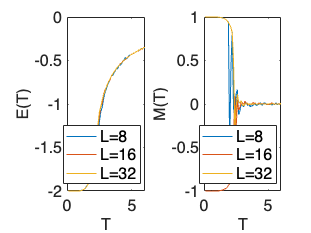

% T1=H(:,end,1);
% T2=H(:,end,2);
% T3=H(:,end,3);
% 
% Hmeans1=mean(H(:,1:(end-1),1),2);
% Hmeans2=mean(H(:,1:(end-1),2),2);
% Hmeans3=mean(H(:,1:(end-1),3),2);
% 
% Smeans1=mean(S(:,1:(end-1),1),2);
% Smeans2=mean(S(:,1:(end-1),2),2);
% Smeans3=mean(S(:,1:(end-1),3),2);
% 
% Hmeansqd1=mean(H(:,1:(end-1),1).^2,2);
% Hmeansqd2=mean(H(:,1:(end-1),2).^2,2);
% Hmeansqd3=mean(H(:,1:(end-1),3).^2,2);
% 
% Smeansqd1=mean(S(:,1:(end-1),1).^2,2);
% Smeansqd2=mean(S(:,1:(end-1),2).^2,2);
% Smeansqd3=mean(S(:,1:(end-1),3).^2,2);

figure

subplot(1,2,1)
plot(data(:,6,1),data(:,1,1))
hold on
plot(data(:,6,1),data(:,1,2))
hold on
plot(data(:,6,1),data(:,1,3))
hold off
legend('L=8','L=16','L=32','location', 'southeast')
xlabel('T')
ylabel('E(T)')

subplot(1,2,2)
plot(data(:,6,1),data(:,2,1))
hold on
plot(data(:,6,1),data(:,2,2))
hold on
plot(data(:,6,1),data(:,2,3))
hold off

legend('L=8','L=16','L=32','location', 'southeast')
xlabel('T')
ylabel('M(T)')
fontsize(16,'points')

C and $\chi$ per spin

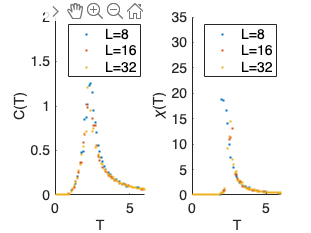

% C1=(Hmeansqd1-Hmeans1.^2)./T1.^2;
% C2=(Hmeansqd2-Hmeans2.^2)./T2.^2;
% C3=(Hmeansqd3-Hmeans3.^2)./T3.^2;
% 
% X1=(Smeansqd1-Smeans1.^2)./T1;
% X2=(Smeansqd2-Smeans2.^2)./T2;
% X3=(Smeansqd3-Smeans3.^2)./T3;

figure

subplot(1,2,1)
scatter(data(:,6,1),data(:,3,1),'.')
hold on
scatter(data(:,6,1),data(:,3,2),'.')
hold on
scatter(data(:,6,1),data(:,3,3),'.')
hold off
legend('L=8','L=16','L=32','location', 'northeast')
xlabel('T')
ylabel('C(T)')

subplot(1,2,2)
scatter(data(:,6,1),data(:,4,1),'.')
hold on
scatter(data(:,6,1),data(:,4,2),'.')
hold on
scatter(data(:,6,1),data(:,4,3),'.')
hold off

legend('L=8','L=16','L=32','location', 'northeast')
xlabel('T')
ylabel('\chi(T)')
xlabel('T')
ylabel('\chi(T)')

fontsize(14,'points')

save("SMCnmax100to1200thousandwextratherm.mat","data")

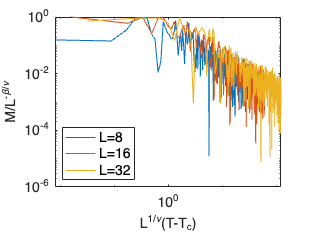

beta=1/8;
nu=1;
gama=7/4;
Tc=2.269;

indbig0=find((data(:,5,1)-Tc)>0);

ttc=data(indbig0,5,1)-Tc;

figure

for L=1:3
    a=sizz(L);
    ss=abs(data(indbig0,2,L)/a^2);
    
    loglog(a^(1/nu)*ttc,ss*a^(beta/nu))
    hold on
end

hold off
legend('L=8','L=16','L=32','location', 'southwest')
xlim tight
xlabel('L^{1/\nu}(T-T_c)')
ylabel('M/L^{-\beta/\nu}')
fontsize(14,'points')

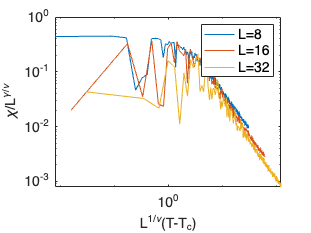


figure

for L=1:3
    a=sizz(L);
    xx=abs(data(indbig0,4,L)/a^2);
    loglog(a^(1/nu)*ttc,xx/a^(gama/nu))
    hold on
end

hold off
legend('L=8','L=16','L=32','location', 'northeast')
xlabel('L^{1/\nu}(T-T_c)')
ylabel('\chi/L^{\gamma/\nu}')
fontsize(14,'points')

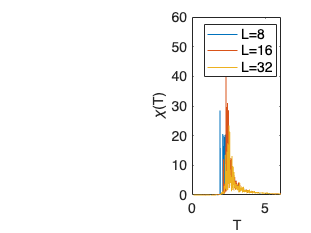


subplot(1,2,2)
plot(data(:,5,1),data(:,4,1)/64)
hold on
plot(data(:,5,1),data(:,4,2)/252)
hold on
plot(data(:,5,1),data(:,4,3)/1024)
hold off

legend('L=8','L=16','L=32','location', 'northeast')
xlabel('T')
ylabel('\chi(T)')
xlabel('T')
ylabel('\chi(T)')

fontsize(14,'points')